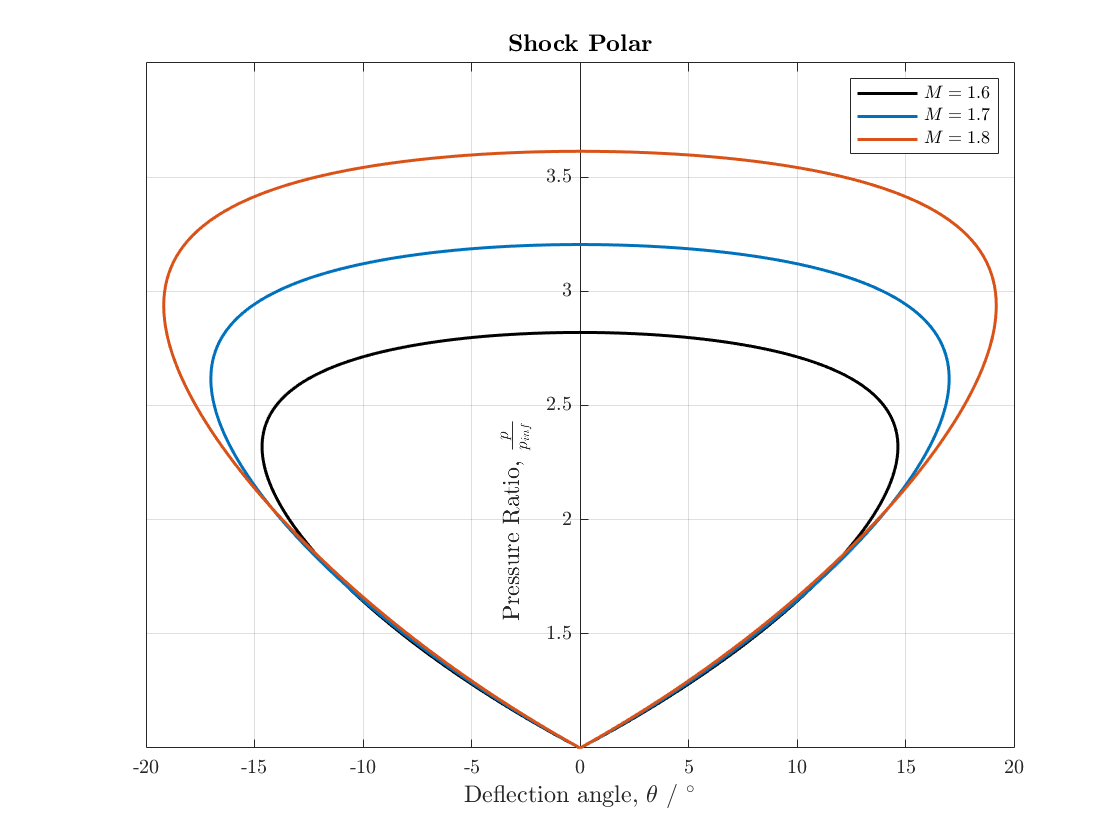

% SHOCK POLAR PLOTTER

% PART OF THE CODE FOR
% AERO 97009 - FINAL YEAR PROJECT
% BUSEMANN BIPLANES

% THOMAS CROSS
% JANUARY 2021

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; clc; clear

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 12 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

M=[1.6,1.7,1.8];
gamma=1.4;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu = asind(1./M); beta_min = mu ; beta_max = 90; n=100;
%beta = zeros(length(M),1)
beta = linspace(beta_min(1,1),beta_max(1),n);
for i = 2:length(M)
holder = linspace(beta_min(1,i),beta_max,n);
beta = [beta;holder];
end
%theta = [30,40]

j=1;
a = (M(1,j).^2).*((sind(beta(j,:))).^2)-1;
b = (2*gamma)/(gamma+1);
c = (M(1,j).^2)*(gamma+(cosd(2.*beta(j,:))));
% Pressure ratio p2/p1 
P = 1+(b.*a);
P = [P,flip(P)];

theta = atand(2.*cotd(beta(j,:)).*(a./(2+c)));
theta = [theta,flip(-theta)];

for j=2:length(M)
a = (M(1,j).^2).*((sind(beta(j,:))).^2)-1;
b = (2*gamma)/(gamma+1);
c = (M(1,j).^2)*(gamma+(cosd(2.*beta(j,:))));
% Pressure ratio p2/p1 
Phold = 1+(b.*a);
Phold = [Phold,flip(Phold)];

thetahold = atand(2.*cotd(beta(j,:)).*(a./(2+c)));
thetahold = [thetahold,flip(-thetahold)];

P = [P;Phold];
theta = [theta;thetahold];
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
plot(theta(1,:),P(1,:),'k','LineWidth',1.5)
hold on
plot(theta(2,:),P(2,:),'LineWidth',1.5,"Color",blue)
plot(theta(3,:),P(3,:),'LineWidth',1.5,"Color",orange)
legend('$M=1.6$','$M=1.7$','$M=1.8$',"FontSize",legsize)
grid on; box on; ax = gca;
ymin=1;ymax=4; ylim([ymin ymax]);
ax.YAxisLocation = 'origin';
title('\textbf{Shock Polar}',"FontSize",tsize)
xlabel("Deflection angle, $\theta$ / $^\circ$","FontSize",lsize)
ylabel("Pressure Ratio, $\frac{p}{p_{inf}}$","FontSize",lsize)
ylh = get(gca,'ylabel'); gyl = get(ylh);   % Object Information
ylp = get(ylh, 'Position');
set(ylh, 'Rotation',90, 'Position',[-3 ymin+0.5*(ymax-ymin)-0.5 ymin+0.5*(ymax-ymin)], 'VerticalAlignment','middle', 'HorizontalAlignment','center')
hold off